## Questão 2

4-QAM (BPSK), probabilidade de erro de bit (Pb)

a) natural (00, 01, 10, 11)

b) Gray (00, 01, 11, 10)

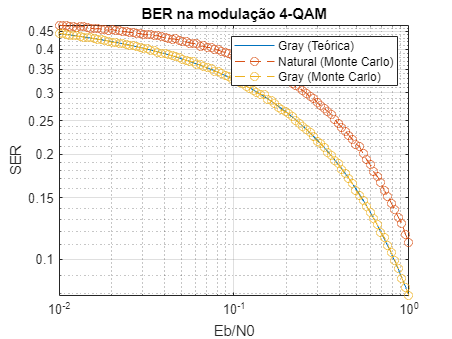

rng('default')

eb_n0 = logspace(-2, 0, 100);

[Pb_teorica, ~] = berawgn(pow2db(eb_n0), 'qam', 4); % Pb
Pb_montecarlo_natural = qam_4_natural(eb_n0);
Pb_montecarlo_gray = qam_4_gray(eb_n0);

figure();
p1 = loglog(eb_n0, Pb_teorica); hold on;
p2 = loglog(eb_n0, Pb_montecarlo_natural, 'LineStyle', '--', 'Marker', 'o');
p3 = loglog(eb_n0, Pb_montecarlo_gray, 'LineStyle', '--', 'Marker', 'o'); hold off;

xlabel('Eb/N0');
ylabel('SER');
legend('Gray (Teórica)', 'Natural (Monte Carlo)', 'Gray (Monte Carlo)');
title('BER na modulação 4-QAM');
grid on